## **steady state evaluation and ROSCO parameters**

clear all
load("bladedata_IEA_15MW.mat"); % load blade data

## **Control region below rated **wind speed 

evaluation of the steady state condition below rated (BR)

parameters:

v_cutin = 3; % cut in speed [m/s]
v_rated = 10; % rated wind speed [m/s]
v_cutout = 25; % velocità di cut out [m/s]
P_rated=15; %rated power
v_discr = 0.5; % wind speed discretisation [m/s]
omega_min = 5; %  minimum rotor speed [RPM]
omega_max = 7.55; % maximum rotor speed [RPM]
omega_discr = 0.05; % rotor speed discretisation [RPM]

resolution

V0_BR=[v_cutin:v_discr:v_rated];
omega=[omega_min:omega_discr:omega_max];

for j=1:length(V0_BR)
for i=1:length(omega)
[THRUST(j,i),TANG(j,i),BENDING(j,i),TORQUE(j,i),POWER(j,i)]=BEM(V0_BR(j),omega(i),0,bladedata);
end
end

[PowerSS_BR,o_i]=max(POWER,[],2);

omegaSS_BR=omega(o_i);
thetaSS_BR=zeros(length(V0_BR),1);

plot

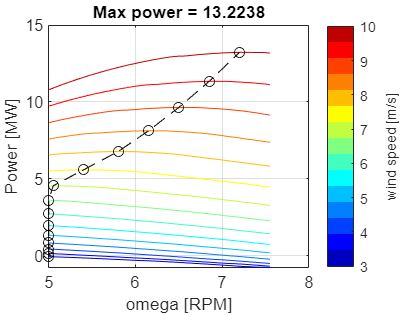

color=jet(length(V0_BR));
clf
for j=1:length(V0_BR)
plot(omega,POWER(j,:),Color=color(j,:))
hold on
end
grid on
xlabel('omega [RPM]');
ylabel('Power [MW]');
colormap(color);
h=colorbar();
h.Label.String='wind speed [m/s]';
caxis([v_cutin, v_rated]);
plot(omegaSS_BR,PowerSS_BR,'ok');
plot(omegaSS_BR,PowerSS_BR,'--k');
title(['Max power = ' num2str(PowerSS_BR(end))])
hold off

PowerSS_BR(end) = P_rated;

plot torque

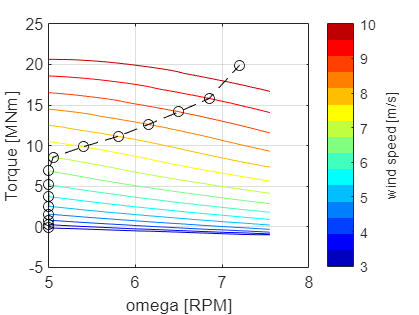

color=jet(length(V0_BR));
clf
for j=1:length(V0_BR)
plot(omega,POWER(j,:)./(omega*pi/30),Color=color(j,:))
hold on
end
grid on
xlabel('omega [RPM]');
ylabel('Torque [MNm]');
colormap(color);
h=colorbar();
h.Label.String='wind speed [m/s]';
caxis([v_cutin, v_rated]);
plot(omegaSS_BR,PowerSS_BR./(omegaSS_BR'*pi/30),'ok');
plot(omegaSS_BR,PowerSS_BR./(omegaSS_BR'*pi/30),'--k');
%title(['Max power = ' num2str(PowerSS_BR(end))])
hold off

## **Control region above rated **wind speed 

blade pitch steady state for above rated (AR)

parameters:

theta_init =10; %blade pitch value of initizialisation for fminsearch (deg)

V0_AR=[V0_BR(end)+v_discr:v_discr:v_cutout];
thetaSS_AR=zeros(length(V0_AR),1);

for j=1:length(V0_AR)
   [thetaSS_AR(j)]=fminsearch(@(theta)searchPower(V0_AR(j),omegaSS_BR(end),theta,P_rated,bladedata),[theta_init]);
end

calcolo potenza e thrust

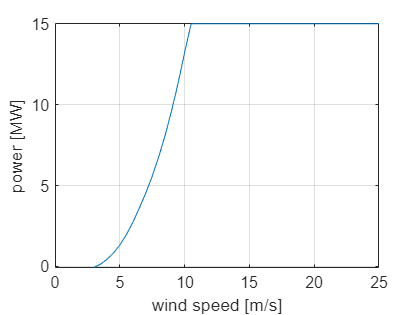

for i=1:length(thetaSS_BR)
[THRUSTSS_BR(i),TANG(i),BENDING(i),TORQUE(i),PowerSS_BR(i)]=BEM(V0_BR(i),omegaSS_BR(i),thetaSS_BR(i),bladedata);
end

for i=1:length(thetaSS_AR)
[THRUSTSS_AR(i),TANG(i),BENDING(i),TORQUE(i),PowerSS_AR(i)]=BEM(V0_AR(i),omegaSS_BR(end),thetaSS_AR(i),bladedata);
end

plot([V0_BR V0_AR],[PowerSS_BR' PowerSS_AR])
xlabel('wind speed [m/s]')
ylabel('power [MW]')
grid on
hold off

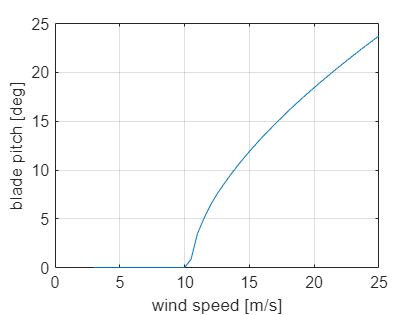

plot([V0_BR V0_AR],[thetaSS_BR;thetaSS_AR])
xlabel('wind speed [m/s]')
ylabel('blade pitch [deg]')
grid on
hold off

## Thrust peak shaving

parameters:

peak_reduction=0.8; % riduction factor of the rated thrust
theta_init =10; %blade pitch value of initizialisation for fminsearch (deg)

maxthrust=THRUSTSS_BR(end)*peak_reduction;
thetamin_BR=zeros(1,length(V0_BR));
i_th=find(V0_BR>interp1(THRUSTSS_BR,V0_BR,maxthrust));
for j=i_th
   [thetamin_BR(j)]=fminsearch(@(theta)searchThrust(V0_BR(j),omegaSS_BR(j),theta,maxthrust,bladedata),[theta_init]);
end

for j=1:length(V0_AR)
    [thetamin_AR(j)]=fminsearch(@(theta)searchThrust(V0_AR(j),omegaSS_BR(end),theta,maxthrust,bladedata),[theta_init]);
end


for j=1:(i_th-1)
   [thetamin_BR(j)]=fminsearch(@(theta)searchPowermax(V0_BR(j),omegaSS_BR(j),theta,maxthrust,bladedata),[theta_init]);
   if thetamin_BR(j)<0
       thetamin_BR(j)=0;
   end
end

find all the steady state values of the system:

theta_SS=max([[thetamin_BR,thetamin_AR];[thetaSS_BR',thetaSS_AR']],[],1);
V0=[V0_BR,V0_AR];
omegaSS=[omegaSS_BR,omegaSS_BR(end)*ones(1,length(V0_AR))];

plot

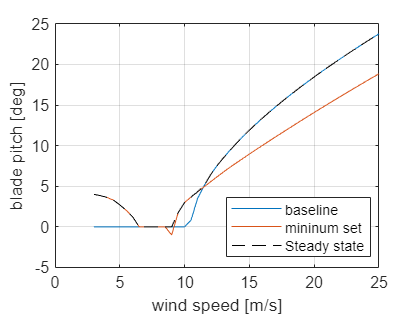

clf
plot([V0_BR V0_AR],[thetaSS_BR;thetaSS_AR])
hold on
plot([V0_BR V0_AR],[thetamin_BR,thetamin_AR])
plot(V0,theta_SS,'--k');
xlabel('wind speed [m/s]')
ylabel('blade pitch [deg]')
legend("baseline","mininum set","Steady state",Location="best")
grid on
hold off

evaluate power loss of the thrust peak shaving module:

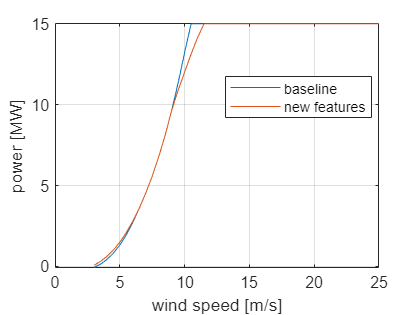

for i=1:length(V0)
    [THRUSTSS(i),TANG_SS(i),BENDING_SS(i),TORQUE_SS(i),powerSS(i)]=BEM(V0(i),omegaSS(i),theta_SS(i),bladedata);
end
plot([V0_BR V0_AR],[PowerSS_BR' PowerSS_AR])
hold on 
plot(V0,powerSS)
xlabel('wind speed [m/s]')
ylabel('power [MW]')
grid on,legend("baseline","new features",Location="best")
hold off

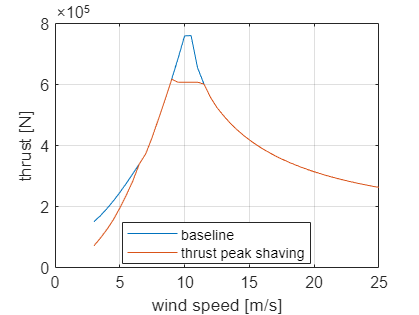



plot([V0_BR V0_AR],[THRUSTSS_BR,THRUSTSS_AR])
hold on
plot(V0,THRUSTSS);
xlabel('wind speed [m/s]')
ylabel('thrust [N]')
grid on, legend("baseline","thrust peak shaving",Location="best")
hold off

## save steady state values  (SS):

SS.WINDSPEED=V0;
SS.ROTSPD=omegaSS;
SS.BLADEPITCH=theta_SS;
SS.THRUST=THRUSTSS*3;
SS.POWER=powerSS;
ROSCO.MINBLADEPITCH=deg2rad([thetamin_BR,thetamin_AR]);
save("SS_IEA15MW","SS")
save("ROSCO_IEA15MW","ROSCO")

ausiliary functions for fminsearch:

function diff=searchPower(V0,omega,theta,Prated,bladedata)
if theta<0
    theta=0;
end
[THRUST,TANG,BENDING,TORQUE,POWER]=BEM(V0,omega,theta,bladedata);

diff=abs(Prated-POWER);
end

function diff=searchThrust(V0,omega,theta,thrust,bladedata)
if theta<0
    theta=0;
end
[THRUST,TANG,BENDING,TORQUE,POWER]=BEM(V0,omega,theta,bladedata);

diff=abs(thrust-THRUST);
end

function out=searchPowermax(V0,omega,theta,Prated,bladedata)
if theta<0
    theta=0;
end
[THRUST,TANG,BENDING,TORQUE,POWER]=BEM(V0,omega,theta,bladedata);

out=-POWER;
end